# Electricity Usage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

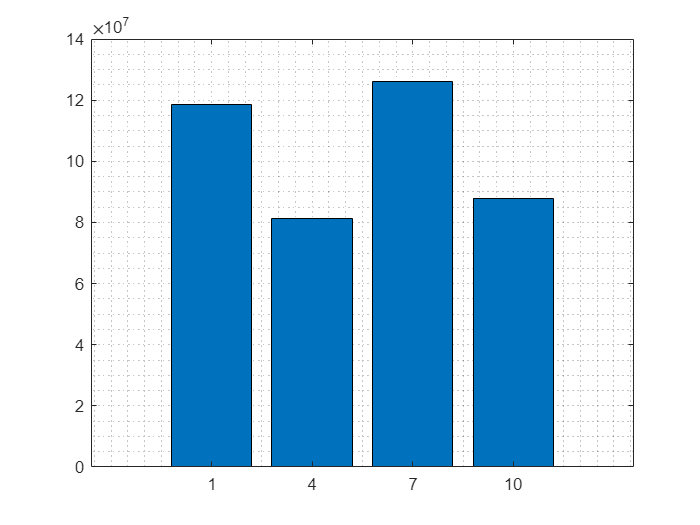

usage = readmatrix("./data/electricity.xlsx", Sheet='usage');
monthly = mean(usage, 2);
mth = 1:12;
bar(mth(1:3:end), monthly(1:3:end))
grid minor

## Task 1

Bars in a bar graph often represent quantities of something best described as text. For instance, each bar of this graph is the electricity usage from the first month of each quarter.

You can use a string array as input to the [`xticklabels`](https://www.mathworks.com/help/matlab/ref/xticklabels.html) function to modify the *x*-axis tick labels.

`xticklabels(["Label 1" "Label 2" ``...``])`

Electricity data are available for download from the U.S. Energy Information Administration: [https://www.eia.gov/electricity/data.cfm](https://www.eia.gov/electricity/data.cfm)

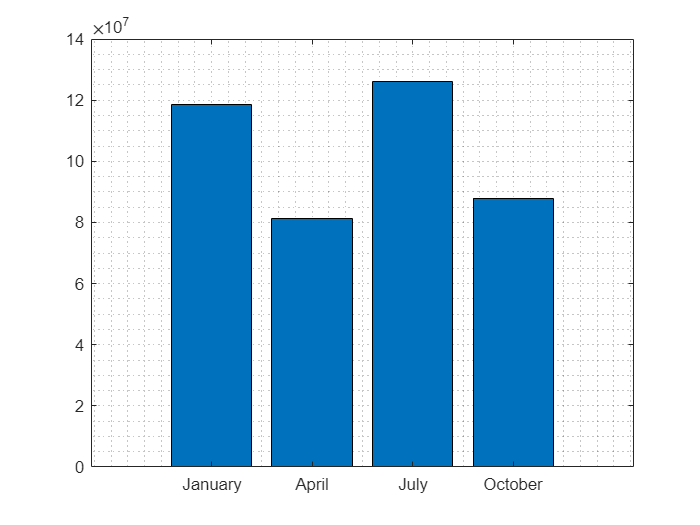

M = ["January" "April" "July" "October"];
xticklabels(M)

## Tasks 2 & 3

The average electricity measurements for all 12 months are in the variable `monthly`. You will visualize the first months of each quarter in context of the rest of the months.

We have the right bars and the right labels, but they aren't in the right spots. Each string in the vector corresponds to an *x*-axis tick. There are four labels, but twelve ticks.

You can set the *x*-axis tick values with the [`xticks`](https://www.mathworks.com/help/matlab/ref/xticks.html) function.

`xticks``([``1` `12``])`

`xticklabels``([``"First Month"` `"Last Month"``])`

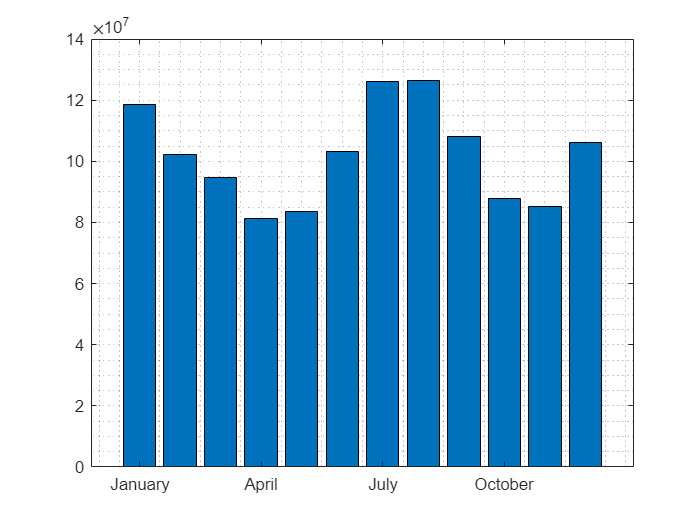

bar(monthly)
grid minor
xticks(1:3:12)
xticklabels(M)